load('natural_freq_x.mat')

% clf
% figure(1)
% for i=1:size(force_frequency_list,2)
%     plot(result(i).x.Time,result(i).x.Data,'DisplayName',['freq=' force_frequency_list(i) ' rad/s'])
%     hold on
% end
% legend
% xlabel('force frequency (rad/s)')
% ylabel('x (m)')
% title('Occilation plot')


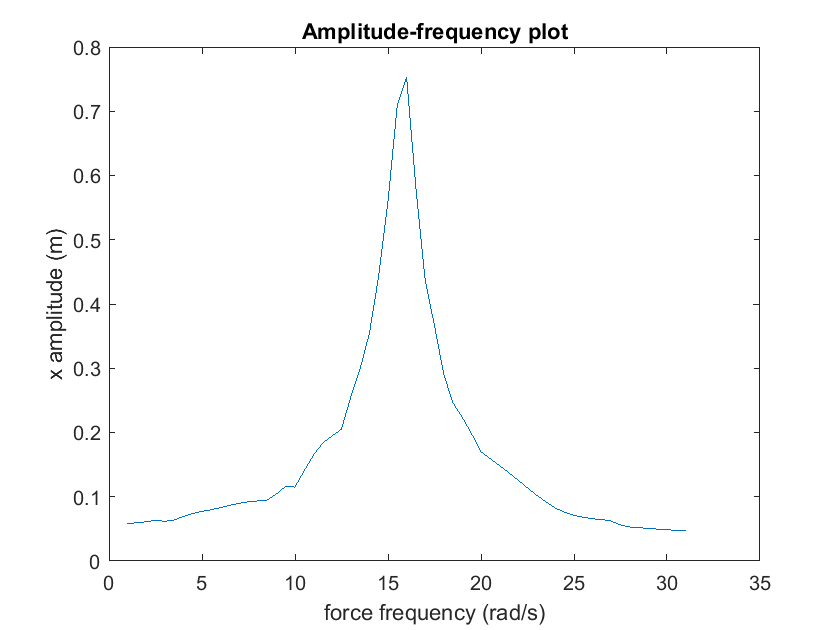

amplitude_list = [];

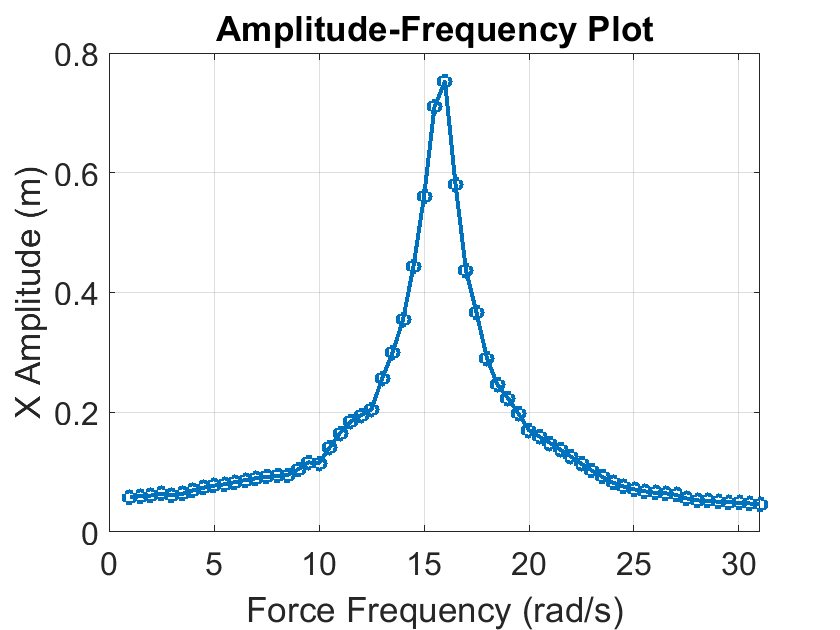

for i = 1:size(force_frequency_list, 2)
    amplitude_list = [amplitude_list max(result(i).x.Data)];
end

figure(2);
plot(force_frequency_list, amplitude_list, 'LineWidth', 2, 'Marker', 'o');
grid on;
set(gca, 'FontSize', 16);
xlabel('Force Frequency (rad/s)', 'FontSize', 16);
ylabel('X Amplitude (m)', 'FontSize', 16);
title('Amplitude-Frequency Plot', 'FontSize', 20);
